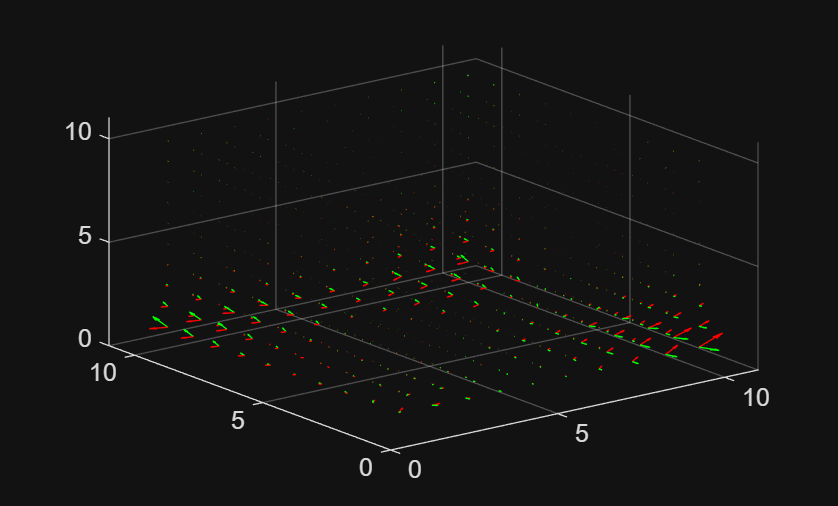

clear all
dt = 1;
c = 1;
omega = 1/50;
dimX = 100;
dimY = 100;
dimZ = 100;
zeros = zeros(dimX,dimY,dimZ);
% E = cat(4,zeros,zeros,zeros);
% B = cat(4,zeros,zeros,zeros);
E = rand(100,100,100,3).*2-1;
B = rand(100,100,100,3).*2-1;

n = 10;
dim = 100;

[xn,yn,zn] = meshgrid(1:n, 1:n, 1:n);
[x,y,z] = meshgrid(1:dim, 1:dim, 1:dim);

v = VideoWriter('C:\Users\srk2687\peaks_animation.avi'); 
open(v);

for t=1:100

B(:,:,1:4,1) = 10*cos(2*pi*t*dt*omega);
% B(:,[1 end],:,1) = 10*cos(2*pi*t*dt*omega);
% B(:,:,[1 end],1) = 10*cos(2*pi*t*dt*omega);

E(:,:,1:4,2) = 10*cos(2*pi*t*dt*omega);
% E(:,[1 end],:,1) = 10*sin(2*pi*t*dt*omega);
% E(:,:,[1 end],1) = 10*sin(2*pi*t*dt*omega);
[C_x,C_y,C_z] = curl(x,y,z,E(:,:,:,1),E(:,:,:,2),E(:,:,:,3));
B = B + dt .* cat(4,C_x,C_y,C_z);
[C_x,C_y,C_z] = curl(x,y,z,B(:,:,:,1),B(:,:,:,2),B(:,:,:,3));
E = E - (dt / c^2) .* cat(4,C_x,C_y,C_z);

P = cross(B,E,4);
writeVideo(v, mat2gray(squeeze(P(:,50,:,:))));
P = P(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);
En = E(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);
Bn = B(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);


% quiver3(xn,yn,zn,P(:,:,:,1),P(:,:,:,2),P(:,:,:,3),'w')

quiver3(xn,yn,zn,En(:,:,:,1),En(:,:,:,2),En(:,:,:,3),'r')
ax = gca; % Get the current axes handle
    xlim(ax, [0 11]); % Set x-axis limits
    ylim(ax, [0 11]); % Set y-axis limits
    zlim(ax, [0 11]); % Set z-axis limits
hold on;
quiver3(xn,yn,zn,Bn(:,:,:,1),Bn(:,:,:,2),Bn(:,:,:,3),'g')
% quiver3(xn,yn,zn,P(:,:,:,1),P(:,:,:,2),P(:,:,:,3),'w')
hold off;
drawnow;


end

close(v);

